# Pràctica Fúmbol

## 1. Introducció

Aquest projecte consisteix a desenvolupar un programa que sigui capaç de reconèixer automàticament imatges on hi hagi una presència significativa de la samarreta del** F.C.Barcelona**.

Per dur a terme el que se'ns demana, utilitzarem imatges normalitzades, histogrames de colors, l'algoritme *chi-quadrat* explicat a teoria i dues formes diferents de dividir/recorrer imatges.

## 2. Selecció del model

Primer de tot, escollim una de les imatges proporcionades del barça com a model, la normalitzem i escollim una subimatge que serà la que ens servirà com a *patró*. Aquesta subimatge no serà més que un tros de la samarreta del F.C.Barcleona on es puguin distingir bé els colors i, per tant, poguem extreure un bon histograma.

La funció que utilitzem per visualitzar l'histograma i decidir si utilitzar la imatge escollida com a model és *histRB*, una funció nostra que conté la funció *histogram*, la qual pertany a una llibreria de gràfics de Matlab. 

La funció que utilitzem per extreure les dades de l'histograma és *histcountRB*, funció nostra que conté la funció *histcounts*, la qual pertany a una llibreria de gràfics de Matlab. D'aquesta, però, ens guardem els resultats ja que seran els que utilitzarem a l'hora de comparar altres imatges.

El valor d'*nbins *s'ha escollit després de fer vàries proves i concloure que aquest valor és amb el que millors resultats hem obtingut.

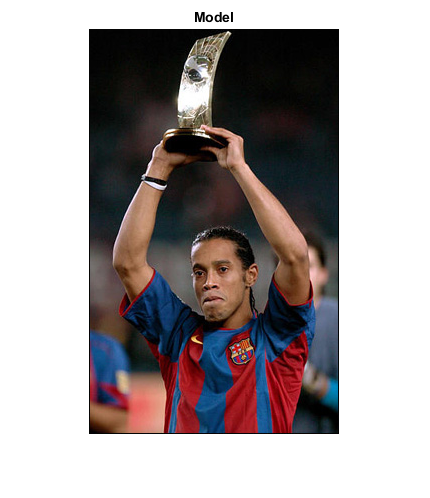

im = imread('model.jpg');
figure, imshow(im); title('Model');

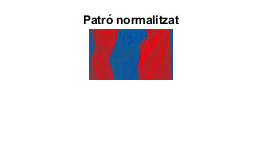


imd = im2double(im);
img = normalizeRGB(imd);
pattern = img(350:400,87:170,:);
figure, imshow(pattern); title('Patró normalitzat')

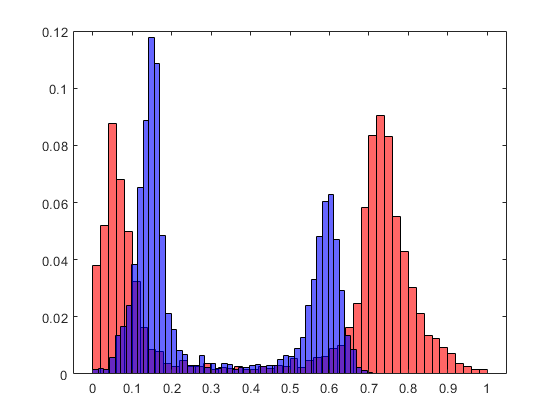


figure, histRB(pattern,50);

[model_red, model_blue] = histcountRB(pattern, 50);

## 3. Comparació d'imatges: Mètode de divisió #1

Agafem una imatge diferent de la del model, la normalitzem i la passem sencera a la funció nostra *computeQuadrants*. Aquesta funció és una funció recursiva que el que fa és cridar a la funció nostra *divideix, *la qual divideix la funció en 4 parts de mida igual (o semblan en cas de que les mides siguin senars). Després, fa l'histograma de cadascuna de les subimatges amb *histcountRB* com s'ha explicat a l'apartat anterior, computa la diferència entre l'histograma model i l'histograma que acabem de generar i fixa el mínim entre els resultats obtingut i els inicials o els computats anteriorment. Finalment fa la crida recursiva amb cada subimatge i torna a fer el mateix. L'objectiu d'aquesta funció és retornar la menor diferència d'histogrames de la imatge que es compara amb el patró.

El mètode utilitzar per dividir la imatge és el *top-down* explicat a teoria amb la diferència que no s'arriba a nivell de pixel sinó que para quan ja ha fet 4 iteracions. Aquesta cota l'hem escollida a base de fer proves i obtenir millors resultats. 

A continuació, passarem totes les imatges de l'equip F.C.Barcelona pel nostre mètode i n'extreurem un llindar amb el qual es puguin reconèixer la majoria d'imatges d'aquest equip i es minimitzin les que pot reconèixer com a falsos positius d'altres equips. El llindar escollit com a diferencia màxima entre els histogrames és de 0'44.

Per visualitzar millor els resulats, hem fet una gràfica de barres amb la funció *bar* de la llibreria de gràfics de Matlab. Les barres que representen la similitud entre les imatges i el patró que estan per sota del llindar seleccionat sortiran pintades de color lila i seran reconegudes com a imatges de l'equip mentre que les que no ho estiguin sortiran en color blau.

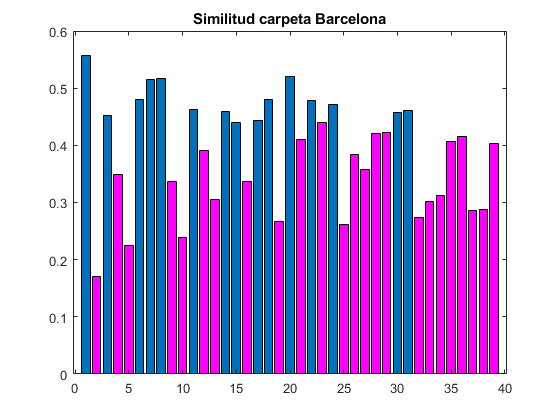

size = 39;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['barcelona/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0,2,2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor', "flat"); title('Similitud carpeta Barcelona');
count = 0;
for i = 1:size
    if y(i) < 0.44
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Total_reconegudes = [num2str(count/size *100),'%']

Total_reconegudes = '61.5385%'

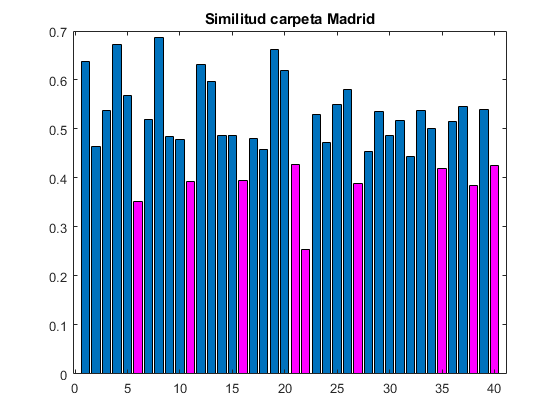

size=40;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['madrid/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Madrid');

count = 0;
for i = 1:size
    if y(i) < 0.44
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end


Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '22.5%'

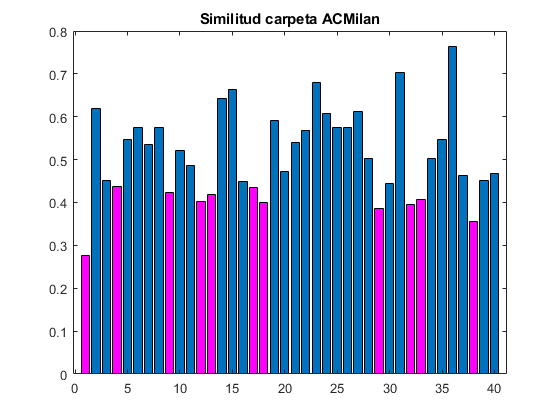

y = zeros(1,size);

for i = 1:size
    novaim = imread(['acmilan/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta ACMilan');

count = 0;
for i = 1:size
    if y(i) < 0.44
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '27.5%'

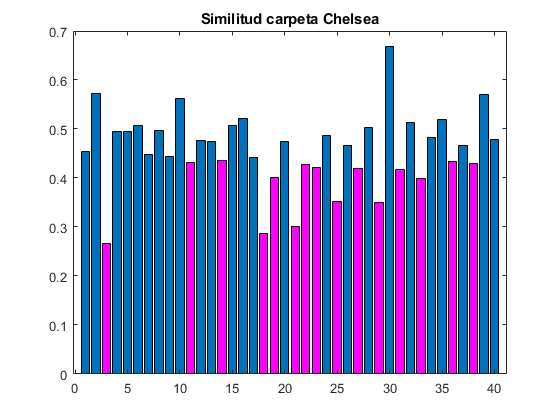

y = zeros(1,size);

for i = 1:size
    novaim = imread(['chelsea/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Chelsea');

count = 0;
for i = 1:size
    if y(i) < 0.44
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '37.5%'

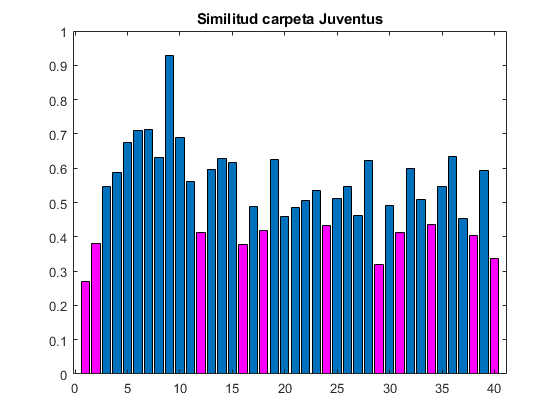

y = zeros(1,size);

for i = 1:size
    novaim = imread(['juventus/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Juventus');

count = 0;
for i = 1:size
    if y(i) < 0.44
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '27.5%'

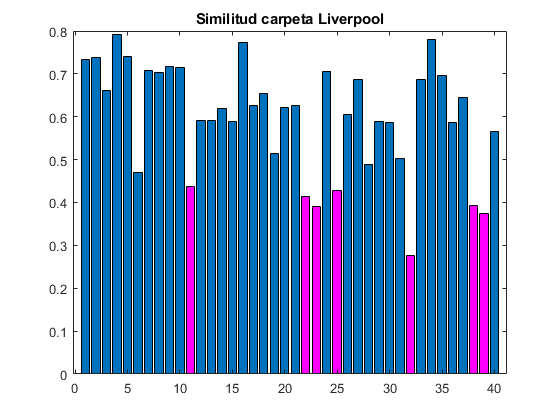

y = zeros(1,size);

for i = 1:size
    novaim = imread(['liverpool/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,1, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Liverpool');

count = 0;
for i = 1:size
    if y(i) < 0.44
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '17.5%'

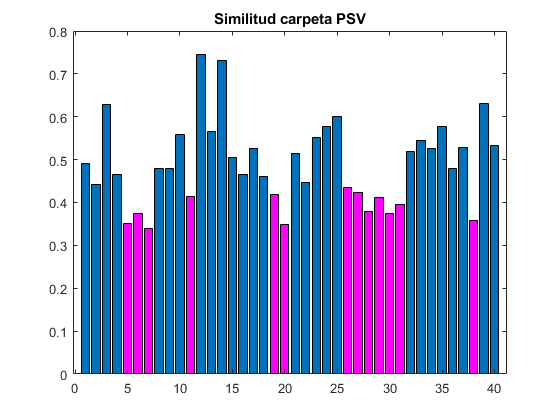

y = zeros(1,size);

for i = 1:size
    novaim = imread(['psv/',num2str(i),'.jpg']);
    novaimg = im2double(novaim);
    novanorm = normalizeRGB(novaimg);    
    [red,blue] = computeQuadrants(model_red, model_blue, novanorm, 50,0, 2, 2);
    y(i) = (red+blue)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta PSV');

count = 0;
for i = 1:size
    if y(i) < 0.44
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '32.5%'

HSV

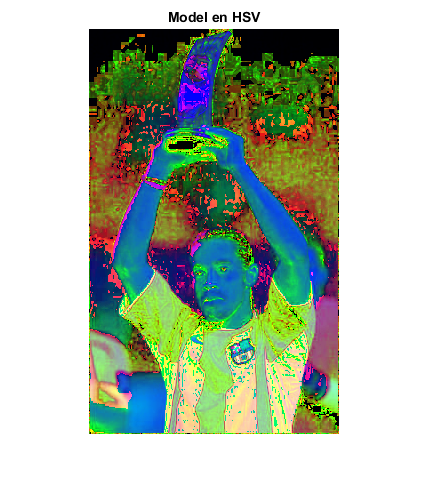

im = imread('model.jpg');
im = rgb2hsv(im);
figure, imshow(im); title('Model en HSV');

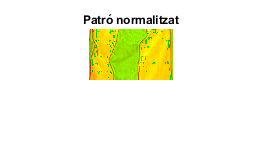

im = normalizeHSV(im);
pattern = im(350:400,87:170,:);
[mh, ms] = histcountHS(pattern, 50);
figure, imshow(pattern); title('Patró normalitzat');


%newim = imread('barcelona/5.jpg');
%newim = rgb2hsv(newim);
%newim = normalizeHSV(newim);

%[h,s] = computeQuadrantsHSV(mh,ms,newim,50,0,2,2);



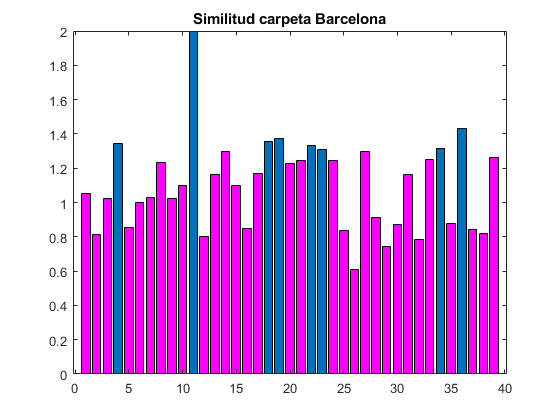

size = 39;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['barcelona/',num2str(i),'.jpg']);
    novaimg = rgb2hsv(novaim);
    novanorm = normalizeHSV(novaimg);    
    [h,s] = computeQuadrantsHSV(mh,ms,novanorm,50,0,2,2);
    y(i) = (h+s)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Barcelona');

count = 0;
for i = 1:size
    if y(i) < 1.3
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Total_reconegudes = [num2str(count/size *100),'%']

Total_reconegudes = '79.4872%'

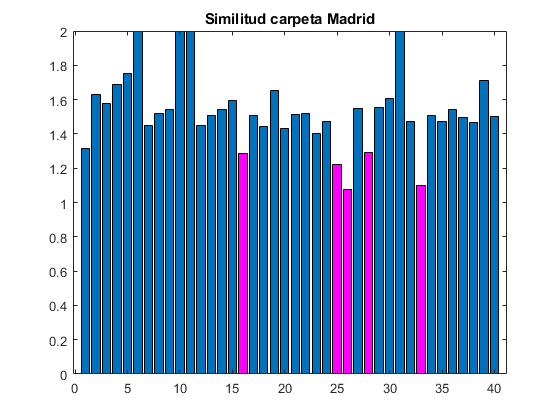

size = 40;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['madrid/',num2str(i),'.jpg']);
    novaimg = rgb2hsv(novaim);
    novanorm = normalizeHSV(novaimg);    
    [h,s] = computeQuadrantsHSV(mh,ms,novanorm,50,0,2,2);
    y(i) = (h+s)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta Madrid');

count = 0;
for i = 1:size
    if y(i) < 1.3
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '12.5%'

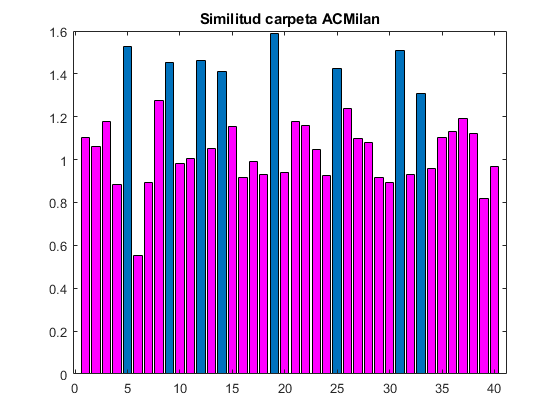

size = 40;
y = zeros(1,size);

for i = 1:size
    novaim = imread(['acmilan/',num2str(i),'.jpg']);
    novaimg = rgb2hsv(novaim);
    novanorm = normalizeHSV(novaimg);    
    [h,s] = computeQuadrantsHSV(mh,ms,novanorm,50,0,2,2);
    y(i) = (h+s)/2;
end

figure, 
b = bar(y,'FaceColor',"flat"); title('Similitud carpeta ACMilan');

count = 0;
for i = 1:size
    if y(i) < 1.3
        b.CData(i,:) = [1 0 1];
        count = count + 1;
    end
end

Falsos_positius = [num2str(count/size *100),'%'] 

Falsos_positius = '80%'